% 论文方法的对照组 基于能量 20220808 YMC GLRT-DT
close all
clear
clc

## 参数设置

pfa         = 0.0001;
Para.J      = 74;            % 目标所占距离单元数
Para.pfa    = pfa;           % 总虚警概率
Para.Pfa1   = 0.2;         % GLRTDT检测器第一虚警概率               % 可修改


## 数据读取

Detector_train_data_add_ref=load('./XL_AUG.mat').clutter2_aug;
size(Detector_train_data_add_ref)

ans =       100000           4         210


% 训练数据 杂波
% Detector_train_data_add_ref = load('./train_data_cl.mat').train_data_cl;       
% size(Detector_train_data_add_ref)      
% % 帧*4极化*距离单元
% Detector_train_data_add_ref = permute(Detector_train_data_add_ref, [1, 3, 2]);
% 测试数据 杂波+目标
Detector_test_data_add_ref = load('./Tg_Cl_data_ZL.mat', 'Tg_Cl_data_ZL').Tg_Cl_data_ZL;   % SCR*帧*4极化*距离单元
size(Detector_test_data_add_ref)

ans =            4          31        7200         210


Detector_test_data_add_ref=permute(Detector_test_data_add_ref,[2,3,1,4]);

## GLRT-DT

% 极化通道融合 PWF or SPAN
% 极化协方差矩阵计算
[Pol_Sigma, wbldis] = get_pol_Covariance_matrix(Detector_train_data_add_ref(:,:,1:end-10));

GLRTDT_pfa = nan(1, size(Detector_train_data_add_ref,1));
for j=1:size(Detector_train_data_add_ref,1)

    HRRP_test_temp = squeeze(Detector_train_data_add_ref(j,:,:));        
    [HRRP_test_temp_pwf] = func_PWF(HRRP_test_temp, Pol_Sigma);
    P_Echo = HRRP_test_temp_pwf(:,1:end-10).^2;
    P_Noise = 1*mean(HRRP_test_temp_pwf(:,end-9:end).^2);
    Hastarget=GLRTDT(P_Echo,P_Noise,Para);

    GLRTDT_pfa(1,j) = Hastarget;

end
mean(GLRTDT_pfa)

ans = 2.5000e-04

## 检测

GLRTDT_result = nan(size(Detector_test_data_add_ref,1), size(Detector_test_data_add_ref,2));

% [MNdetector_Th1, MNdetector_Pfcell] = MNdetector_get_param(pfa, MNdetector_Th2_list(k), wbldis);
for i=1:size(Detector_test_data_add_ref,1)
    i
    for j=1:size(Detector_test_data_add_ref,2)

        HRRP_test_temp = squeeze(Detector_test_data_add_ref(i,j,:,:));        
        [HRRP_test_temp_pwf] = func_PWF(HRRP_test_temp, Pol_Sigma);
        P_Echo = HRRP_test_temp_pwf(:,1:end-10).^2;
        P_Noise = mean(HRRP_test_temp_pwf(:,end-9:end).^2);
        Hastarget=GLRTDT(P_Echo,P_Noise,Para);

        GLRTDT_result(i,j) = Hastarget;

    end
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

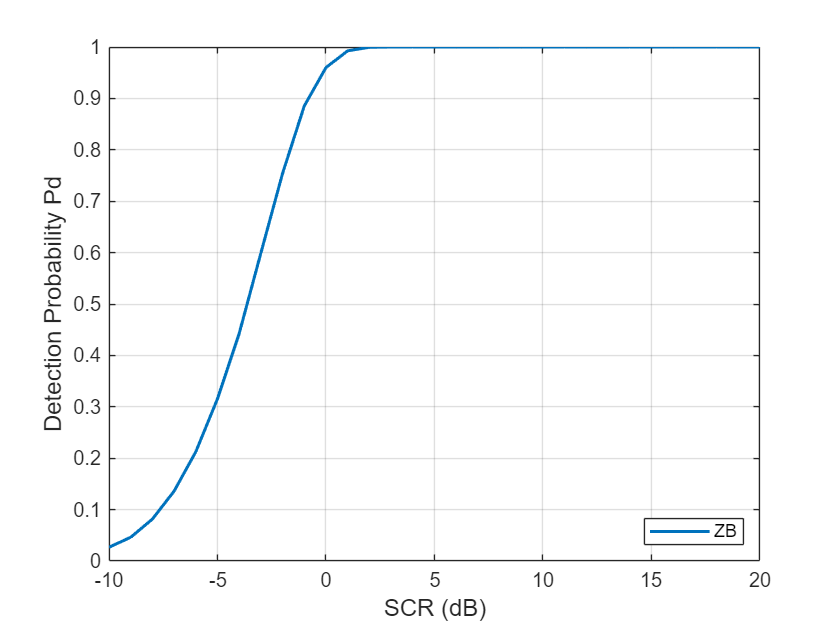


figure;
SCR_list = -10:1:20;  % 保证这个是你用来生成数据的实际 SCR 列表
mean_pd = mean(GLRTDT_result,2);  % [num_th2 x num_scr]
plot(SCR_list, mean_pd', 'LineWidth', 1.5);  % 横坐标用 SCR_list
xlim([-10 20]);            % 设置横坐标范围
ylim([0 1]);               % 设置纵坐标范围（检测概率范围是0~1）
xlabel('SCR (dB)', 'FontSize', 12);
ylabel('Detection Probability Pd', 'FontSize', 12);
legend('ZB', 'Location','southeast');grid on;

save('./GLRTDT_ZL.mat', 'GLRTDT_result');

## 子函数--获取极化协方差矩阵

function [Sigma, wbldis] = get_pol_Covariance_matrix(Cl_data)

HRRP_test = [];
for i=1:size(Cl_data,1)
    HRRP_test = cat(2, HRRP_test, squeeze(Cl_data(i,:,:)));
end
s_hh = HRRP_test(1,:);
s_vh = HRRP_test(3,:);
s_hv = HRRP_test(2,:);
s_vv = HRRP_test(4,:);
s_hh_p = HRRP_test(1,:) .* conj(HRRP_test(1,:)); 
s_vh_p = HRRP_test(3,:) .* conj(HRRP_test(3,:));
s_hv_p = HRRP_test(2,:) .* conj(HRRP_test(2,:)); 
s_vv_p = HRRP_test(4,:) .* conj(HRRP_test(4,:));
Sigma11 = mean(s_hh_p);
Sigma22 = mean(s_vh_p);
Sigma33 = mean(s_hv_p);
Sigma44 = mean(s_vv_p);
Sigma21 = mean(conj(s_hh).*s_vh);
Sigma31 = mean(conj(s_hh).*s_hv);
Sigma41 = mean(conj(s_hh).*s_vv);
Sigma32 = mean(conj(s_vh).*s_hv);
Sigma42 = mean(conj(s_vh).*s_vv);
Sigma43 = mean(conj(s_hv).*s_vv);
Sigma12 = mean(conj(s_vh).*s_hh);
Sigma13 = mean(conj(s_hv).*s_hh);
Sigma14 = mean(conj(s_vv).*s_hh);
Sigma23 = mean(conj(s_hv).*s_vh);
Sigma24 = mean(conj(s_vv).*s_vh);
Sigma34 = mean(conj(s_vv).*s_hv);
Sigma = [Sigma11,Sigma12,Sigma13,Sigma14;Sigma21,Sigma22,Sigma23,Sigma24;...
         Sigma31,Sigma32,Sigma33,Sigma34; Sigma41,Sigma42,Sigma43,Sigma44];

[hrrp_num, N_hrrp] = size(s_hh);
hrrp_pwf      = zeros(1, hrrp_num*N_hrrp);
for k=1:hrrp_num
    for L=1:N_hrrp
        hrrp_pwf((k-1)*N_hrrp+L) = real([s_hh(k,L);s_vh(k,L);s_hv(k,L);s_vv(k,L)]' ...
            * inv(Sigma) * [s_hh(k,L);s_vh(k,L);s_hv(k,L);s_vv(k,L)]);
    end
end
hrrp_pwf = hrrp_pwf ./ mean(hrrp_pwf) ;
wbldis = wblfit((hrrp_pwf), 0.05);
p_1 = wbldis(1);
q_1 = wbldis(2);
end

## 子函数--极化白化滤波

function [HRRP_pwf] = func_PWF(HRRP_test, Sigma)
s_hh = HRRP_test(1,:);
s_vh = HRRP_test(3,:);
s_hv = HRRP_test(2,:);
s_vv = HRRP_test(4,:);
HRRP_pwf = zeros(size(s_hh));
for i = 1:length(s_hh)
    HRRP_pwf(1,i) = real([s_hh(i);s_vh(i);s_hv(i);s_vv(i)]' * inv(Sigma) * [s_hh(i);s_vh(i);s_hv(i);s_vv(i)]); %#ok<MINV> 
end
end

## 子函数--GLRT-DT

function Hastarget=GLRTDT(P_Echo,P_Noise,Para)
th1=-P_Noise*log(Para.Pfa1);
t1=P_Echo>th1;
P_Echo=t1.*P_Echo;
k=sum(t1);
Sumk=sum(P_Echo);
WindowTh = gaminv(1-Para.pfa/(1-(1-exp(-th1/P_Noise))^Para.J),k,P_Noise)+k.*th1;
Hastarget=Sumk>3*WindowTh;
end